# Population Tooling - PPT Demo

In this document, the steps for using the PPT tool of the population study tooling are discussed. The goal of this Livescript is to show some of the functionalities of the tool which may be used to generate a ppt. 

## Getting Started

First, the correct tooling needs to be imported.

import BMMO_XY.populationTooling.*

## Creating a PPT

First, we create a new PPT in the current directory called "demo.pptx". If "demo.pptx" already exist, the file will be extended instead.

demo_ppt = PPT('demo');

The title of the PPT is set using

demo_ppt.setTitle('Demonstration of the PPT class');

In this livescript we use some very simple plots. Normally, one would use the plots created by for example the plotting tooling of the population tooling. Therefore, it is important to properly store your plots, like shown in the demoPlotting livescript. For now, we stick to creating some generic plots with their own title.

plot1 = figure; plot(1:10); title('plot1');
plot2 = figure; plot(10:-1:1); title('plot2');

A plot is added to the PPT by inserting a new slide and simultaneously placing a plot inside. For example by executing:

demo_ppt.insertFigures('Simple plots', 'please find plot1', plot1);

## Creating a new Chapter

A new chapter is created using

demo_ppt.insertChapter('Compare plots');

In this new chapter we may want to show multiple plots next to each other for comparison. Similar to what was shown earlier, we do this using

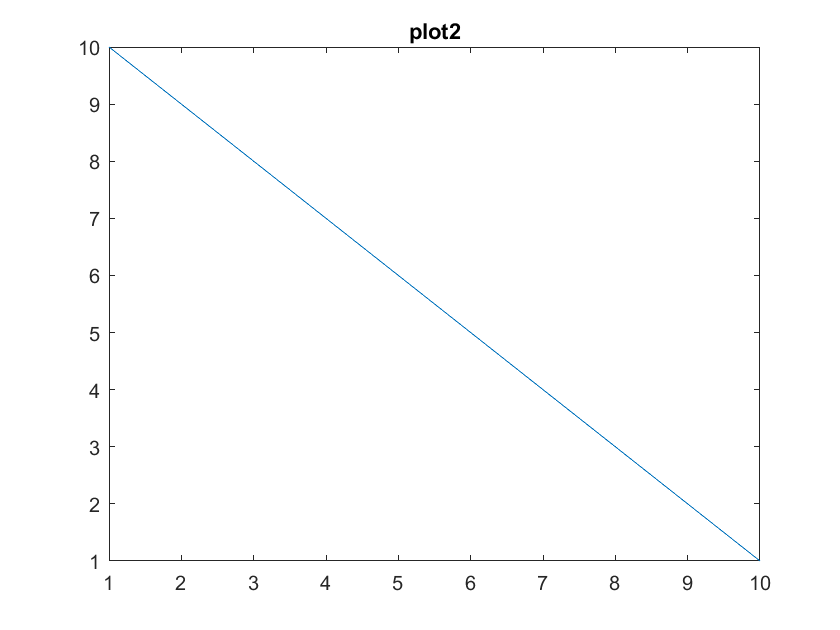

demo_ppt.insertFigures('Simple plots', 'please find plot1 and plot2', [plot1 plot2]);

## Finishing up

After we are done plotting, we close the figures that were opened in line 4 and 5 and save and close the ppt and Voila!

close(plot1, plot2)
demo_ppt.closeFile

If you encounter any issues during running of this livescript, clearing the demo_ppt object in the workspace will likely solve this.